# Modeling and Analyzing a Battery Charging Profile

## BatteryProfile.Team6 | Engineering Pathway Program

#### Yovany Gaspar - Project Manager and QA 

#### Sa Nguyen - Modeling 

#### Maya Maestas - Analysis and Validation

#### Kailey Neri - Documentation and Visualization

## Project Overview

This project analyzes a measured lithium-ion battery charging profile from Cycle 1 of the MathWorks battery dataset. The team selected the first 301 seconds of the charging interval and modeled the measured voltage response using the required one-RC equation. The required model was then compared with a shifted one-RC model and a two-RC model to evaluate how the starting voltage and multiple response rates affected model accuracy. Measured current data were retained for the current, power, delivered-energy, and resistive-loss calculations because the project does not provide a separate current-versus-time equation. Model performance was evaluated using the fitted time constants, R-squared values, and RMSE values. The analysis also examined voltage rate of change, charging-time estimates, delivered energy, resistive losses, and validation against the results reported by Sa and Maya. The dataset is stored in the repository’s `data` folder so the complete analysis, figures, and summary tables can be reproduced from GitHub.

## Problem Statement

The purpose of this project is to use Cycle 1 from the MathWorks lithium-ion battery dataset to model the voltage response during a selected charging interval. The analysis compares the measured voltage with fitted voltage models and calculates charging rate, charging time, power, delivered energy, and resistive energy loss.

**Requirements, Constraints, and Success Criteria**

The project must load the original battery dataset, isolate one charging interval, and fit the required fixed-3.6-volt one-RC voltage model. The fitted time constant, R-squared value, and RMSE must be reported. The project must also include voltage, current, and power plots, calculate the voltage rate of change, estimate charging times, determine delivered energy and resistive loss, and summarize the results in clearly labeled tables.

One constraint is that the required model assumes the voltage begins at zero volts, while the measured battery begins at a nonzero voltage. The dataset also uses a dynamic fast-charging policy that cannot be completely represented by one time constant. The project does not require a separate current-versus-time model, so measured current values are used for the electrical calculations.The project is considered successful when the Live Script runs from beginning to end without errors, reproduces the required figures and tables, clearly explains the assumptions and limitations, and can be repeated from the GitHub repository.

## Proposed Solution

The final analysis uses Sa’s Cycle 1 selection and the first 301 seconds of the charging interval so the results remain consistent with the team’s original work. The required fixed-3.6-volt one-RC model is presented as the baseline. A shifted one-RC model and a two-RC model are included as additional comparisons to determine whether accounting for the nonzero starting voltage and multiple response rates improves the fit. Measured voltage and current values are used to calculate power, delivered energy, and resistive energy loss. The final results are also compared with the values reported by Sa and Maya to confirm that the calculations are reproducible and to explain differences caused by the methods used.

## Main Steps

The main steps are to load and inspect the dataset, isolate Cycle 1, define the selected charging interval, fit the required and optional voltage models, create the required electrical plots, calculate the analytical results, validate the calculations, interpret the engineering meaning, and export the final figures and tables for the GitHub repository.

**Challenges**

One challenge is that the measured battery voltage begins above zero volts, while the required one-RC equation assumes an initial voltage of zero. This causes the required model to fit the measured data poorly. Another challenge is that the dynamic fast-charging policy includes more than one charging stage, so one time constant cannot fully represent the complete voltage response. The project also does not provide a separate current-versus-time equation. Therefore, the measured current data are used for the current plot, power calculation, delivered-energy calculation, and resistive-loss estimate. This avoids introducing unsupported assumptions about the battery’s resistance, capacitance, or charging-control system.

## Approach and Methodology

The battery dataset was loaded into MATLAB, and Cycle 1 was isolated for analysis. Time was converted to seconds, and the data were sorted by time. Rows containing invalid time, voltage, or current values were removed, along with duplicate time points. The selected 0-to-301-second charging interval was then extracted for the model fitting and analytical calculations. The measured voltage was fitted using the required fixed-3.6-volt one-RC equation, followed by the shifted one-RC and two-RC equations. Each model was evaluated using its fitted parameters, R-squared value, and RMSE. The measured voltage and fitted curves were plotted together to compare how closely each model represented the measured data.  

Power was calculated from corresponding measured voltage and current samples. Delivered energy was determined by numerically integrating the power-versus-time curve using MATLAB’s `trapz` function. Resistive power loss was calculated using the measured current and the internal-resistance values provided in the dataset. Invalid resistance values, when present, were replaced with the median valid resistance from the selected interval before the resistive energy loss was integrated over time. The voltage rate of change was calculated numerically at selected points in the charging interval. Charging-time estimates, energy results, and model statistics were organized into summary tables. The final calculations were then compared with the values reported by Sa and Maya using absolute and percent differences

## Data Loading and Charging-Segment Selection

%% Project Setup and Data Loading
clear
clc
close all
format compact

% Locate the repository root. The file may be stored in the live_script folder
% or directly in the repository root during testing.
try
    activeFile = matlab.desktop.editor.getActiveFilename;
catch
    activeFile = '';
end

if ~isempty(activeFile)
    liveScriptFolder = fileparts(activeFile);
    [candidateRoot, folderName] = fileparts(liveScriptFolder);
    if strcmpi(folderName,'live_script')
        repoRoot = candidateRoot;
    else
        repoRoot = liveScriptFolder;
    end
else
    repoRoot = pwd;
end

figureFolder = fullfile(repoRoot,'results','figures');
tableFolder = fullfile(repoRoot,'results','tables');
animationFolder = fullfile(repoRoot,'results','animations');

if ~isfolder(figureFolder), mkdir(figureFolder); end
if ~isfolder(tableFolder), mkdir(tableFolder); end
if ~isfolder(animationFolder), mkdir(animationFolder); end

% Ask the user to select the battery dataset.
[selectedFile,selectedFolder] = uigetfile( ...
    {'*.mat','MATLAB Data Files (*.mat)'}, ...
    'Select singleCellLifeTimeData.mat', ...
    'singleCellLifeTimeData.mat');

% Stop the script if no file is selected.
if isequal(selectedFile,0)
    error(['No dataset was selected. Run the Live Script again and ' ...
        'select singleCellLifeTimeData.mat.'])
end

% Load the selected file.
dataSource = fullfile(selectedFolder,selectedFile);
loadedData = load(dataSource,'data');

% Confirm that the selected file contains the required data variable.
if ~isfield(loadedData,'data')
    error(['The selected MAT file does not contain a variable named data. ' ...
        'Select the original singleCellLifeTimeData.mat file.'])
end

data = loadedData.data;

if ~istable(data)
    error('The variable named data must be a MATLAB table.')
end

requiredVariables = {'DateTime','Current','Voltage', ...
    'Internal_Resistance'};

availableVariables = data.Properties.VariableNames;
missingVariables = setdiff(requiredVariables,availableVariables);

if ~isempty(missingVariables)
    error('The selected dataset is missing these variables: %s', ...
        strjoin(missingVariables,', '))
end

fprintf('Data source: %s\n',dataSource)

Data source: C:\Users\yngas\OneDrive\Desktop\BatteryProfile_Team6\singleCellLifeTimeData.mat


fprintf('MATLAB version: %s\n',version)

MATLAB version: 25.1.0.2973910 (R2025a) Update 1


curveFitInfo = ver('curvefit');
if isempty(curveFitInfo)
    warning('BatteryProfile:MissingCurveFittingToolbox', ...
        '%s','Curve Fitting Toolbox was not detected.')
else
    fprintf('Curve Fitting Toolbox version: %s\n',curveFitInfo.Version)
end

Curve Fitting Toolbox version: 25.1



head(data,5)

    Data_Point    Test_Time          DateTime          Step_Time    Step_Index    Cycle_Index    Current    Voltage    Charge_Capacity    Discharge_Capacity    Charge_Energy    Discharge_Energy       dV/dt       Internal_Resistance    Temperature
    __________    _________    ____________________    _________    __________    ___________    _______    _______    _______________    __________________    _____________    ________________    ___________    ___________________    ___________

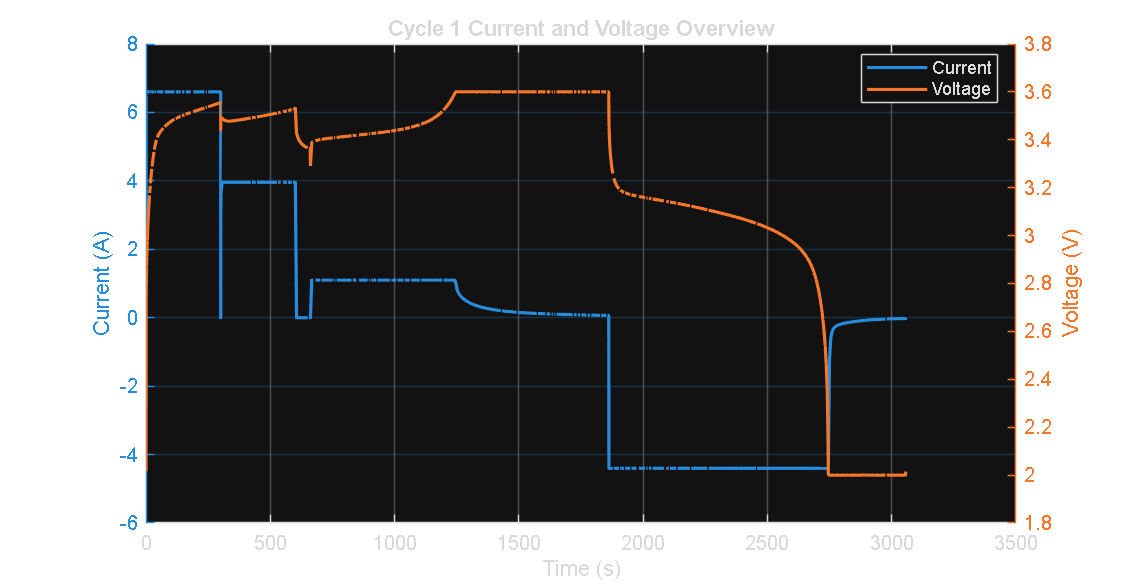

%% Prepare the Selected Battery Dataset

% Use Cycle 1 when the selected file contains a Cycle_Index column.
% Otherwise, use all rows from the selected smaller dataset.
if ismember('Cycle_Index',data.Properties.VariableNames)
    cycleData = data(data.Cycle_Index == 1,:);
    datasetLabel = 'Cycle 1';
else
    cycleData = data;
    datasetLabel = 'Selected battery dataset';
end

assert(~isempty(cycleData), ...
    'The selected dataset does not contain any usable rows.')

cycleData.Time_s = seconds( ...
    cycleData.DateTime - cycleData.DateTime(1));

cycleData = sortrows(cycleData,'Time_s');

validRows = isfinite(cycleData.Time_s) & ...
    isfinite(cycleData.Voltage) & isfinite(cycleData.Current);
cycleData = cycleData(validRows,:);
[~,uniqueTimeIndex] = unique(cycleData.Time_s,'stable');
cycleData = cycleData(uniqueTimeIndex,:);

figure('Color','w','Position',[100 100 1050 550])
yyaxis left
plot(cycleData.Time_s,cycleData.Current,'LineWidth',1.6)
ylabel('Current (A)')
yyaxis right
plot(cycleData.Time_s,cycleData.Voltage,'LineWidth',1.6)
ylabel('Voltage (V)')
xlabel('Time (s)')
title('Cycle 1 Current and Voltage Overview')
grid on
legend('Current','Voltage','Location','best')
exportgraphics(gcf,fullfile(figureFolder,'cycle1_overview.png'), ...
    'Resolution',200)


modelEnd_s = 301;
chargeData = cycleData(cycleData.Time_s <= modelEnd_s,:);
assert(height(chargeData) > 10, ...
    'The selected charging interval does not contain enough data points.')

x = double(chargeData.Time_s);
voltageMeasured = double(chargeData.Voltage);
currentMeasured = double(chargeData.Current);

fprintf('Selected cycle: 1\n')

Selected cycle: 1


fprintf('Selected interval: %.4f to %.4f s\n',x(1),x(end))

Selected interval: 0.0000 to 300.9504 s


fprintf('Average measured current: %.6f A\n', ...
    mean(currentMeasured,'omitnan'))

Average measured current: 5.786586 A


The complete Cycle 1 figure provides context for the dynamic charging policy. The remaining analysis uses the same 0-to-301-second segment that Sa used in the original model. This interval is described as the selected initial charging segment, not as the complete battery life cycle.

## Task 1: Fit the Required Voltage Equation

# Task 1: Fit the Required Voltage Equation

#### The required model is         V(t)=Vmax�(1−e−t/τ)

where Vmax�=3.6 V and τ is the fitted time constant. This model is presented first because it is specified in the original project instructions. However, the measured battery begins at a nonzero voltage, while the required equation assumes an initial voltage of zero. This difference is expected to limit the accuracy of the required model.

%% Required Fixed-3.6-Volt One-RC Model
VmaxKnown = 3.6;

requiredEquation = fittype( ...
    'Vmax*(1-exp(-x/tau))', ...
    'independent','x', ...
    'dependent','y', ...
    'coefficients','tau', ...
    'problem','Vmax');

[requiredFit,requiredGOF] = fit( ...
    x,voltageMeasured,requiredEquation, ...
    'problem',VmaxKnown, ...
    'Lower',1e-4, ...
    'Upper',Inf, ...
    'StartPoint',10);

requiredVoltage = requiredFit(x);

fprintf('Required-model tau: %.6f s\n',requiredFit.tau)

Required-model tau: 0.387074 s


fprintf('Required-model R-squared: %.6f\n',requiredGOF.rsquare)

Required-model R-squared: 0.245827


fprintf('Required-model RMSE: %.6f V\n',requiredGOF.rmse)

Required-model RMSE: 0.385398 V


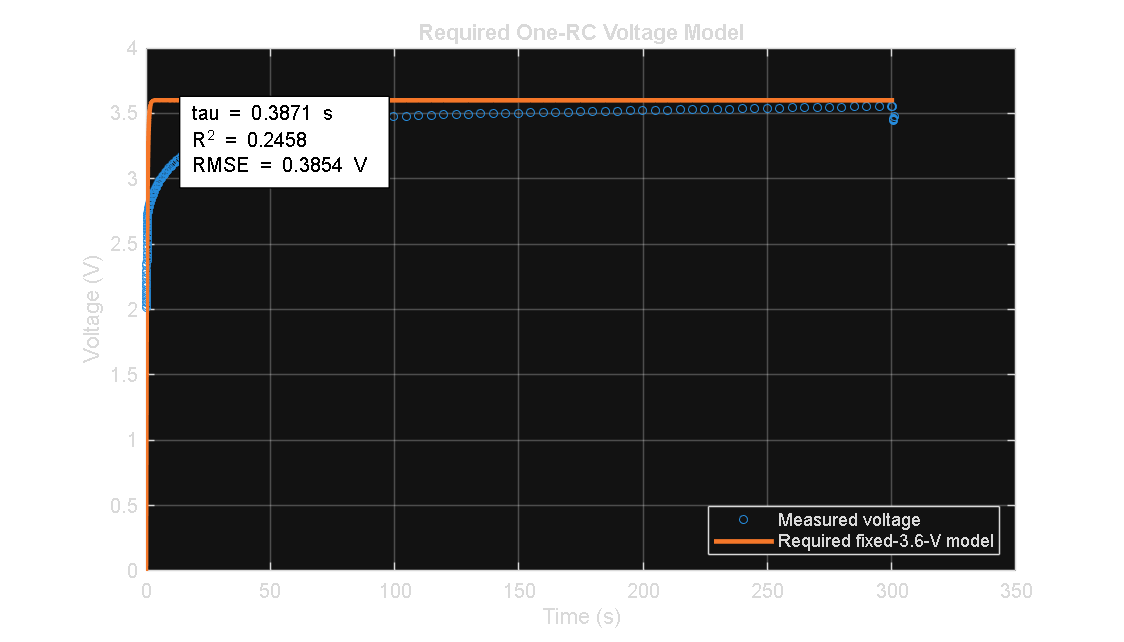


figure('Color','w','Position',[100 100 1050 600])
plot(x,voltageMeasured,'o','MarkerSize',4, ...
    'DisplayName','Measured voltage')
hold on
plot(x,requiredVoltage,'LineWidth',2.3, ...
    'DisplayName','Required fixed-3.6-V model')
xlabel('Time (s)')
ylabel('Voltage (V)')
title('Required One-RC Voltage Model')
legend('Location','southeast')
grid on
annotation('textbox',[0.16 0.70 0.25 0.15], ...
    'String',sprintf('tau = %.4f s\nR^2 = %.4f\nRMSE = %.4f V', ...
    requiredFit.tau,requiredGOF.rsquare,requiredGOF.rmse), ...
    'FitBoxToText','on', ...
    'BackgroundColor','white', ...
    'Color','black', ...
    'EdgeColor','black')
exportgraphics(gcf,fullfile(figureFolder,'required_model_fit.png'), ...
    'Resolution',200)

The required model is expected to have a weaker fit because it predicts zero volts at time zero, while the measured battery starts at a nonzero voltage. A weak fit does not mean the code failed. It shows a limitation of applying the ideal capacitor equation directly to this battery segment.

## Additional Voltage Models Based on Sa’s Work

Sa tested a shifted one-RC model and a two-RC model. The shifted model includes the measured starting voltage. The two-RC model includes fast and slow voltage responses. These models are useful comparisons, but they do not replace the required fixed-3.6-volt baseline.

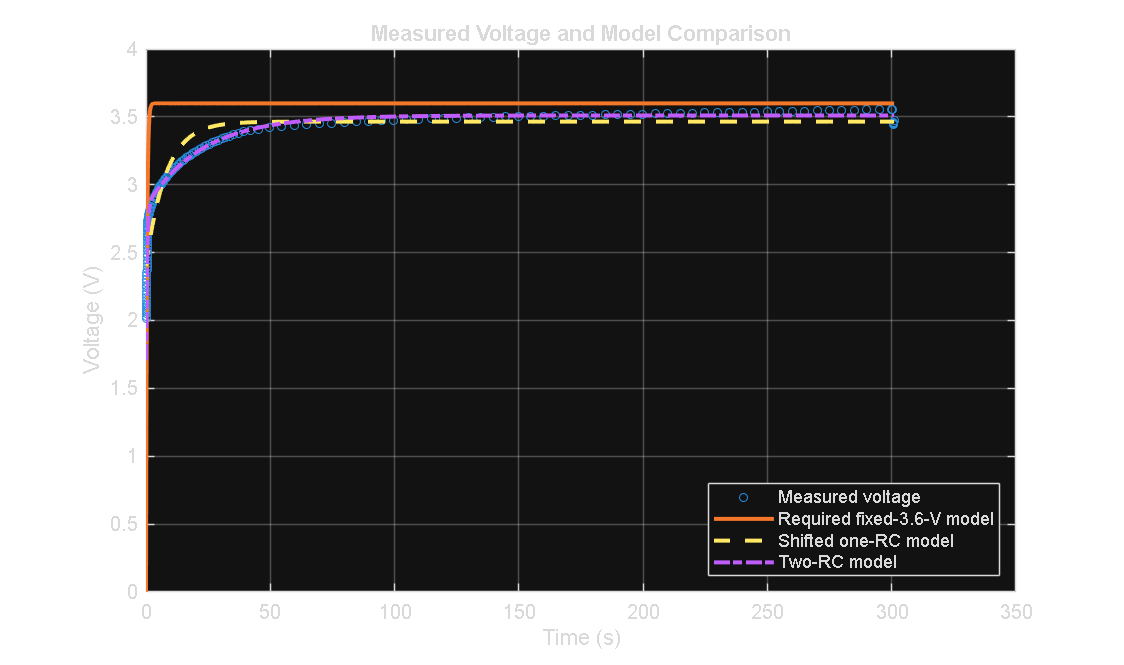

%% Shifted One-RC and Two-RC Voltage Models
shiftedFit = [];
shiftedR2 = NaN;
shiftedRMSE = NaN;
shiftedV0 = NaN;
shiftedA = NaN;
shiftedTau = NaN;

try
    shiftedEquation = fittype( ...
        'V0 + A*(1-exp(-x/tau))', ...
        'independent','x', ...
        'dependent','y', ...
        'coefficients',{'V0','A','tau'});
    shiftedOptions = fitoptions(shiftedEquation);
    shiftedOptions.Lower = [0 0 1e-4];
    shiftedOptions.Upper = [4 4 Inf];
    shiftedOptions.StartPoint = [2.0 1.0 8.0];

    [shiftedFit,shiftedGOF] = fit( ...
        x,voltageMeasured,shiftedEquation,shiftedOptions);
    shiftedVoltage = shiftedFit(x);
    shiftedR2 = shiftedGOF.rsquare;
    shiftedRMSE = shiftedGOF.rmse;
    shiftedV0 = shiftedFit.V0;
    shiftedA = shiftedFit.A;
    shiftedTau = shiftedFit.tau;
catch fitError
    shiftedVoltage = NaN(size(x));
    warning(fitError.identifier,'%s',fitError.message)
end

twoRCFit = [];
twoRCR2 = NaN;
twoRCRMSE = NaN;
twoV0 = NaN;
twoA1 = NaN;
twoA2 = NaN;
twoTau1 = NaN;
twoTau2 = NaN;

try
    twoRCEquation = fittype( ...
        ['V0 + A1*(1-exp(-x/tau1))' ...
         ' + A2*(1-exp(-x/tau2))'], ...
        'independent','x', ...
        'dependent','y', ...
        'coefficients',{'V0','A1','A2','tau1','tau2'});
    twoRCOptions = fitoptions(twoRCEquation);
    twoRCOptions.Lower = [0 0 0 1e-4 3];
    twoRCOptions.Upper = [4 4 4 Inf Inf];
    twoRCOptions.StartPoint = [2.0 1.0 0.5 1.0 100.0];

    [twoRCFit,twoRCGOF] = fit( ...
        x,voltageMeasured,twoRCEquation,twoRCOptions);
    twoRCVoltage = twoRCFit(x);
    twoRCR2 = twoRCGOF.rsquare;
    twoRCRMSE = twoRCGOF.rmse;
    twoV0 = twoRCFit.V0;
    twoA1 = twoRCFit.A1;
    twoA2 = twoRCFit.A2;
    twoTau1 = twoRCFit.tau1;
    twoTau2 = twoRCFit.tau2;
catch fitError
    twoRCVoltage = NaN(size(x));
    warning(fitError.identifier,'%s',fitError.message)
end

figure('Color','w','Position',[100 100 1100 650])
plot(x,voltageMeasured,'o','MarkerSize',4, ...
    'DisplayName','Measured voltage')
hold on
plot(x,requiredVoltage,'LineWidth',2.0, ...
    'DisplayName','Required fixed-3.6-V model')
if ~isempty(shiftedFit)
    plot(x,shiftedVoltage,'--','LineWidth',2.0, ...
        'DisplayName','Shifted one-RC model')
end
if ~isempty(twoRCFit)
    plot(x,twoRCVoltage,'-.','LineWidth',2.0, ...
        'DisplayName','Two-RC model')
end
xlabel('Time (s)')
ylabel('Voltage (V)')
title('Measured Voltage and Model Comparison')
legend('Location','southeast')
grid on
exportgraphics(gcf,fullfile(figureFolder,'model_comparison.png'), ...
    'Resolution',200)


ModelComparison = table( ...
    ["Required fixed-3.6-V one-RC";"Shifted one-RC";"Two-RC"], ...
    [1;3;5], ...
    [requiredGOF.rsquare;shiftedR2;twoRCR2], ...
    [requiredGOF.rmse;shiftedRMSE;twoRCRMSE], ...
    [string(requiredFit.tau);string(shiftedTau); ...
     string(twoTau1) + " and " + string(twoTau2)], ...
    'VariableNames',{'Model','FittedParameters','R_Squared', ...
    'RMSE_V','TimeConstants_s'});

disp(ModelComparison)

                Model                FittedParameters    R_Squared     RMSE_V        TimeConstants_s   
    _____________________________    ________________    _________    ________    _____________________
    "Required fixed-3.6-V one-RC"           1             0.24583       0.3854    "0.38707"            
    "Shifted one-RC"                        3             0.91093      0.13316    "7.8995"             
    "Two-RC"                                5             0.99132     0.041795    "0.44737 and 22.5125"


writetable(ModelComparison,fullfile(tableFolder,'model_comparison.csv'))

[~,bestModelIndex] = min(ModelComparison.RMSE_V,[],'omitnan');
fprintf('Best numerical voltage fit by RMSE: %s\n', ...
    char(ModelComparison.Model(bestModelIndex)))

Best numerical voltage fit by RMSE: Two-RC


The two-RC model is expected to give the strongest numerical fit because it has more fitted parameters and represents both fast and slow voltage changes. The improvement in R-squared and RMSE must be balanced against the added complexity. The required one-RC model remains the official baseline for the assignment.

## Task 2: Plot Voltage, Current, and Power

Treatment of current data: The project provides a voltage equation but does not provide a current-versus-time equation. The fitted value tau gives the product RC, but it does not separately determine resistance, capacitance, or the charger’s changing current commands. For this reason, the final report uses measured current for the current plot, power calculation, delivered-energy calculation, and resistive-loss estimate. No modeled current curve is claimed.

%% Measured Voltage, Current, and Power
powerSigned_W = voltageMeasured .* currentMeasured;
meanCurrent_A = mean(currentMeasured,'omitnan');

if meanCurrent_A >= 0
    powerDelivered_W = powerSigned_W;
    currentSignDescription = ...
        'Positive current represents charging in the selected interval';
else
    powerDelivered_W = -powerSigned_W;
    currentSignDescription = ...
        'Negative current represents charging in the selected interval';
end

fprintf('Current sign convention: %s\n',currentSignDescription)

Current sign convention: Positive current represents charging in the selected interval


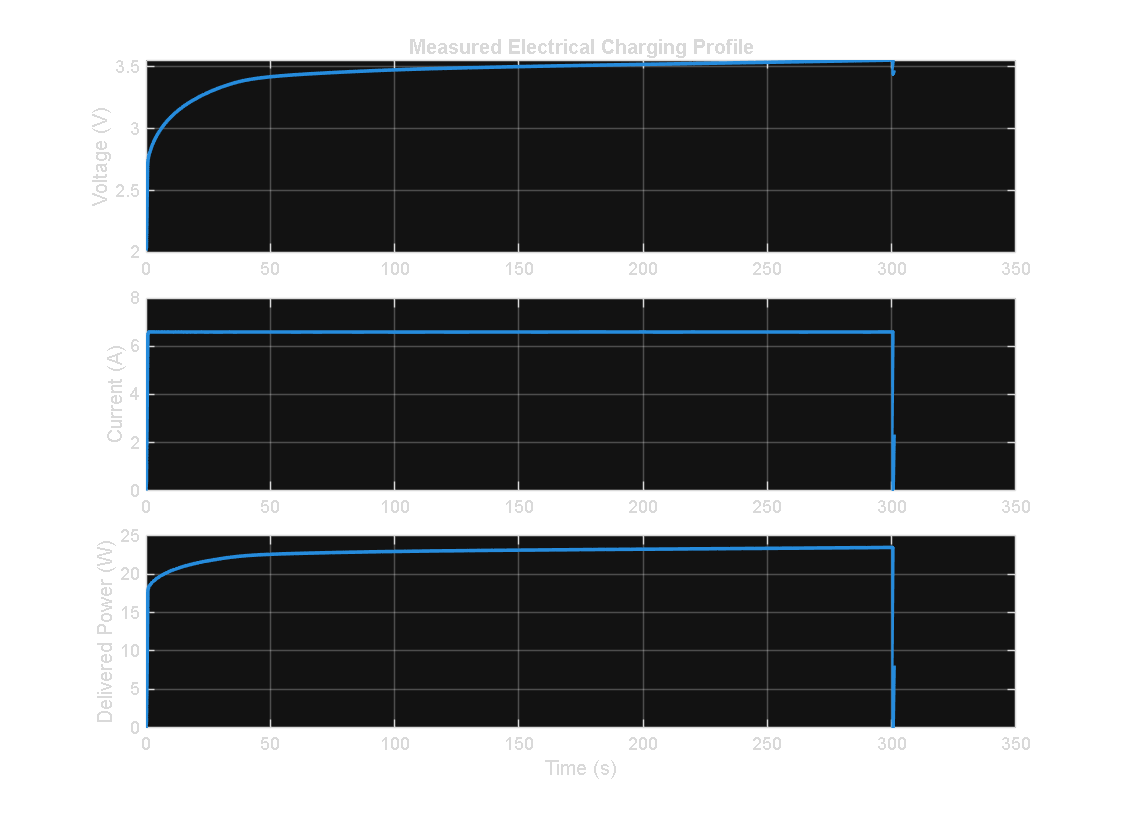


figure('Color','w','Position',[100 100 1100 800])
tiledlayout(3,1,'TileSpacing','compact')
nexttile
plot(x,voltageMeasured,'LineWidth',1.8)
ylabel('Voltage (V)')
title('Measured Electrical Charging Profile')
grid on
nexttile
plot(x,currentMeasured,'LineWidth',1.8)
ylabel('Current (A)')
grid on
nexttile
plot(x,powerDelivered_W,'LineWidth',1.8)
ylabel('Delivered Power (W)')
xlabel('Time (s)')
grid on
exportgraphics(gcf,fullfile(figureFolder,'voltage_current_power.png'), ...
    'Resolution',200)

Power is calculated from matching measured samples using P(t) = V(t)I(t). This is the required electrical profile. The repeated current graphs from Sa’s model sections were removed because the same measured current was used in every model and therefore produced identical current plots.

## Task 3: Compute Analytical Results

%% Step 1: Voltage Rate of Change
voltageRate_V_per_s = gradient(voltageMeasured,x);
keyTimes_s = [2;20;200];
keyIndex = zeros(size(keyTimes_s));

for k = 1:numel(keyTimes_s)
    [~,keyIndex(k)] = min(abs(x-keyTimes_s(k)));
end

keyVoltages_V = voltageMeasured(keyIndex);
keyRates_V_per_s = voltageRate_V_per_s(keyIndex);
chargingStage = ["Steep initial rise";"Transition";"Plateau"];

RateOfChange = table(chargingStage,keyTimes_s,keyVoltages_V, ...
    keyRates_V_per_s, ...
    'VariableNames',{'ChargingStage','Time_s','Voltage_V', ...
    'dVdt_V_per_s'});
disp(RateOfChange)

       ChargingStage        Time_s    Voltage_V    dVdt_V_per_s
    ____________________    ______    _________    ____________
    "Steep initial rise"       2       2.8412         0.058114 
    "Transition"              20       3.2385         0.011477 
    "Plateau"                200       3.5208       0.00033329 


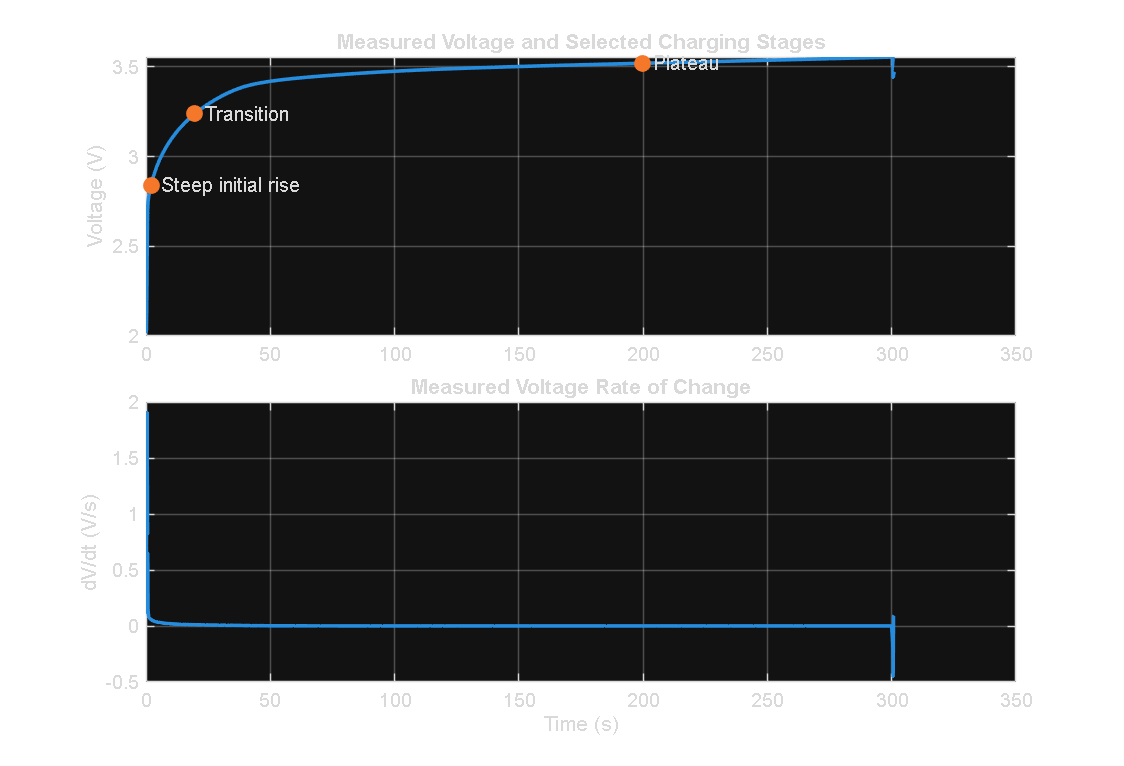

writetable(RateOfChange,fullfile(tableFolder,'rate_of_change.csv'))

figure('Color','w','Position',[100 100 1100 750])
tiledlayout(2,1,'TileSpacing','compact')
nexttile
plot(x,voltageMeasured,'LineWidth',1.8)
hold on
scatter(x(keyIndex),keyVoltages_V,70,'filled')
for k = 1:numel(keyIndex)
    text(x(keyIndex(k))+4,keyVoltages_V(k),chargingStage(k), ...
        'FontSize',10)
end
ylabel('Voltage (V)')
title('Measured Voltage and Selected Charging Stages')
grid on
nexttile
plot(x,voltageRate_V_per_s,'LineWidth',1.8)
xlabel('Time (s)')
ylabel('dV/dt (V/s)')
title('Measured Voltage Rate of Change')
grid on
exportgraphics(gcf,fullfile(figureFolder,'voltage_rate_of_change.png'), ...
    'Resolution',200)

%% Step 2: Time to 80 Percent and Practical Full Charge
% Required-model definitions.
time80Required_s = -requiredFit.tau*log(0.20);
timePracticalFullRequired_s = 5*requiredFit.tau;
practicalFullPercent = 100*(1-exp(-5));

% Measured definitions based on the rise within Sa's selected interval.
measuredMinVoltage_V = min(voltageMeasured);
[maxMeasuredVoltage_V,maxVoltageIndex] = max(voltageMeasured);
measured80Threshold_V = measuredMinVoltage_V + ...
    0.80*(maxMeasuredVoltage_V-measuredMinVoltage_V);
measured80Index = find(voltageMeasured >= measured80Threshold_V,1,'first');
measured80Time_s = x(measured80Index);
timeMaxMeasuredVoltage_s = x(maxVoltageIndex);

fprintf('Required-model time to 80%%: %.6f s\n',time80Required_s)

Required-model time to 80%: 0.622972 s


fprintf('Required-model practical full time (5 tau): %.6f s\n', ...
    timePracticalFullRequired_s)

Required-model practical full time (5 tau): 1.935370 s


fprintf('Five time constants represent %.4f%% of the model maximum.\n', ...
    practicalFullPercent)

Five time constants represent 99.3262% of the model maximum.


fprintf('Measured 80%%-rise time: %.6f s\n',measured80Time_s)

Measured 80%-rise time: 20.486000 s


fprintf('Measured maximum voltage time in selected interval: %.6f s\n', ...
    timeMaxMeasuredVoltage_s)

Measured maximum voltage time in selected interval: 300.484500 s


%% Step 3: Delivered Energy
energyDelivered_J = trapz(x,powerDelivered_W);
energyDelivered_Wh = energyDelivered_J/3600;

fprintf('Delivered energy: %.6f J (%.6f Wh)\n', ...
    energyDelivered_J,energyDelivered_Wh)

Delivered energy: 6859.263458 J (1.905351 Wh)


%% Step 4: Resistive Energy Loss
% Use the time-varying Internal_Resistance measurements from the dataset.
resistance_Ohm = double(chargeData.Internal_Resistance);
validResistance = isfinite(resistance_Ohm) & resistance_Ohm > 0;
assert(any(validResistance), ...
    'No valid internal-resistance measurements were found in the interval.')

representativeResistance_Ohm = median(resistance_Ohm(validResistance));
resistanceUsed_Ohm = resistance_Ohm;
resistanceUsed_Ohm(~validResistance) = representativeResistance_Ohm;

resistivePowerLoss_W = currentMeasured.^2 .* resistanceUsed_Ohm;
resistiveEnergyLoss_J = trapz(x,resistivePowerLoss_W);
resistiveEnergyLoss_Wh = resistiveEnergyLoss_J/3600;

fprintf('Representative internal resistance: %.6f Ohm\n', ...
    representativeResistance_Ohm)

Representative internal resistance: 0.017634 Ohm


fprintf('Resistive energy loss: %.6f J (%.6f Wh)\n', ...
    resistiveEnergyLoss_J,resistiveEnergyLoss_Wh)

Resistive energy loss: 230.445111 J (0.064013 Wh)


%% Step 5: Final Summary Table
SummaryResults = table( ...
    ["Selected cycle"; ...
     "Selected interval end"; ...
     "Required-model tau"; ...
     "Required-model R-squared"; ...
     "Required-model RMSE"; ...
     "Voltage rate at 2 s"; ...
     "Voltage rate at 20 s"; ...
     "Voltage rate at 200 s"; ...
     "Required-model time to 80 percent"; ...
     "Required-model practical full time"; ...
     "Practical full percentage at 5 tau"; ...
     "Measured 80 percent-rise threshold"; ...
     "Measured time to 80 percent rise"; ...
     "Maximum measured voltage"; ...
     "Measured practical full-charge time in selected interval"; ...
     "Delivered energy"; ...
     "Delivered energy"; ...
     "Representative internal resistance"; ...
     "Resistive energy loss"; ...
     "Resistive energy loss"], ...
    [1;modelEnd_s;requiredFit.tau;requiredGOF.rsquare; ...
     requiredGOF.rmse;keyRates_V_per_s(1);keyRates_V_per_s(2); ...
     keyRates_V_per_s(3);time80Required_s; ...
     timePracticalFullRequired_s;practicalFullPercent; ...
     measured80Threshold_V;measured80Time_s;maxMeasuredVoltage_V; ...
     timeMaxMeasuredVoltage_s;energyDelivered_J;energyDelivered_Wh; ...
     representativeResistance_Ohm;resistiveEnergyLoss_J; ...
     resistiveEnergyLoss_Wh], ...
    ["cycle";"s";"s";"unitless";"V";"V/s";"V/s";"V/s"; ...
     "s";"s";"%";"V";"s";"V";"s";"J";"Wh";"Ohm"; ...
     "J";"Wh"], ...
    'VariableNames',{'Metric','Value','Units'});

disp(SummaryResults)

                              Metric                                Value         Units   
    __________________________________________________________    __________    __________
    "Selected cycle"                                                       1    "cycle"   
    "Selected interval end"                                              301    "s"       
    "Required-model tau"                                             0.38707    "s"       
    "Required-model R-squared"                                       0.24583    "unitless"
    "Required-model RMSE"                                             0.3854    "V"       
    "Voltage rate at 2 s"                                           0.058114    "V/s"     
    "Voltage rate at 20 s"                                          0.011477    "V/s"     
    "Voltage rate at 200 s"                                       0.00033329   

writetable(SummaryResults,fullfile(tableFolder,'summary_results.csv'))

## Validation Against Sa’s Submitted Results

Sa’s PDF is used as a traceable reference, not as a substitute for a clean MATLAB run. The following tables compare the current run with Sa’s reported fitted parameters, goodness-of-fit statistics, and raw analytical values. Small differences may occur because of software settings or numerical precision. Large differences should be investigated before submission.

%% Sa Model-Fit Cross-Check
saModelMetric = [ ...
    "Shifted one-RC V0";"Shifted one-RC amplitude"; ...
    "Shifted one-RC tau";"Shifted one-RC R-squared"; ...
    "Shifted one-RC RMSE";"Two-RC V0";"Two-RC fast amplitude"; ...
    "Two-RC slow amplitude";"Two-RC tau1";"Two-RC tau2"; ...
    "Two-RC R-squared";"Two-RC RMSE"];

saModelReference = [2.402;1.064;7.902;0.9109;0.1332; ...
    1.708;1.133;0.6708;0.4474;22.51;0.9913;0.0418];
saModelCurrent = [shiftedV0;shiftedA;shiftedTau;shiftedR2; ...
    shiftedRMSE;twoV0;twoA1;twoA2;twoTau1;twoTau2; ...
    twoRCR2;twoRCRMSE];
saModelAbsoluteDifference = abs(saModelCurrent-saModelReference);
saModelPercentDifference = 100*saModelAbsoluteDifference ./ ...
    max(abs(saModelReference),eps);

SaModelValidation = table(saModelMetric,saModelReference,saModelCurrent, ...
    saModelAbsoluteDifference,saModelPercentDifference, ...
    'VariableNames',{'Metric','SaPDFValue','CurrentRunValue', ...
    'AbsoluteDifference','PercentDifference'});
disp(SaModelValidation)

              Metric              SaPDFValue    CurrentRunValue    AbsoluteDifference    PercentDifference
    __________________________    __________    _______________    __________________    _________________
    "Shifted one-RC V0"              2.402           2.4015            0.00045245             0.018836    
    "Shifted one-RC amplitude"       1.064           1.0639            5.5851e-05            0.0052491    
    "Shifted one-RC tau"             7.902           7.8995             0.0025088             0.031749    
    "Shifted one-RC R-squared"      0.9109          0.91093            2.8847e-05            0.0031669    
    "Shifted one-RC RMSE"           0.1332          0.13316            4.2527e-05             0.031927    
    "Two-RC V0"                      1.708           1.7075            0.00050763

writetable(SaModelValidation, ...
    fullfile(tableFolder,'sa_model_validation.csv'))
%% Sa Raw-Analysis Cross-Check
saRawMetric = ["Measured 80 percent threshold"; ...
    "Measured time to 80 percent rise";"Maximum measured voltage"; ...
    "Time of maximum measured voltage";"Delivered energy"];
saRawReference = [3.2476;20.4860;3.5557;300.4845;6859.3];
saRawCurrent = [measured80Threshold_V;measured80Time_s; ...
    maxMeasuredVoltage_V;timeMaxMeasuredVoltage_s;energyDelivered_J];
saRawAbsoluteDifference = abs(saRawCurrent-saRawReference);
saRawPercentDifference = 100*saRawAbsoluteDifference ./ ...
    max(abs(saRawReference),eps);

SaRawValidation = table(saRawMetric,saRawReference,saRawCurrent, ...
    saRawAbsoluteDifference,saRawPercentDifference, ...
    'VariableNames',{'Metric','SaPDFValue','CurrentRunValue', ...
    'AbsoluteDifference','PercentDifference'});
disp(SaRawValidation)

                  Metric                  SaPDFValue    CurrentRunValue    AbsoluteDifference    PercentDifference
    __________________________________    __________    _______________    __________________    _________________
    "Measured 80 percent threshold"         3.2476          3.2476             1.088e-05            0.00033502    
    "Measured time to 80 percent rise"      20.486          20.486                     0                     0    
    "Maximum measured voltage"              3.5557          3.5557              1.97e-05            0.00055404    
    "Time of maximum measured voltage"      300.48          300.48                     0                     0    
    "Delivered energy"                      6859.3          6859.3              0.036542            0.00053274    


writetable(SaRawValidation, ...
    fullfile(tableFolder,'sa_raw_validation.csv'))

## Validation Against Maya’s Analysis

Maya’s analysis is used as an independent method check. The current run reproduces her voltage-rate, charge-time, delivered-energy, equivalent-resistance, and resistive-loss calculations using the same stated formulas. This comparison verifies that her calculations are reproducible, but it does not replace the primary project results because her charge times come from the slow two-RC time constant and her loss estimate uses a fitted equivalent resistance rather than the resistance measurements in the dataset.

%% Reproduce Maya's Calculation Methods for Direct Validation
if ~isempty(twoRCFit)
    mayaTime80Current_s = 1.6*twoTau2;
    mayaTime100Current_s = 5*twoTau2;

    mayaAverageCurrent_A = mean(currentMeasured,'omitnan');
    mayaR0_Ohm = resistanceUsed_Ohm(1);
    mayaRFast_Ohm = twoA1/mayaAverageCurrent_A;
    mayaRSlow_Ohm = twoA2/mayaAverageCurrent_A;
    mayaEquivalentR_Ohm = mayaR0_Ohm + mayaRFast_Ohm + mayaRSlow_Ohm;
    mayaPowerLoss_W = mayaAverageCurrent_A^2 * mayaEquivalentR_Ohm;
    mayaEnergyLossCurrent_J = mayaPowerLoss_W * (x(end)-x(1));
else
    mayaTime80Current_s = NaN;
    mayaTime100Current_s = NaN;
    mayaEquivalentR_Ohm = NaN;
    mayaEnergyLossCurrent_J = NaN;
end

mayaMetric = ["Peak voltage rate near 2 s"; ...
    "Plateau voltage rate near 200 s";"Time to 80 percent"; ...
    "Time to 100 percent";"Delivered energy"; ...
    "Equivalent resistance";"Internal resistive energy loss"];
mayaReference = [0.058114;0.00033329;36.0208;112.5650;6859.3;0.3337;3362.3];
mayaCurrent = [keyRates_V_per_s(1);keyRates_V_per_s(3); ...
    mayaTime80Current_s;mayaTime100Current_s;energyDelivered_J; ...
    mayaEquivalentR_Ohm;mayaEnergyLossCurrent_J];
mayaAbsoluteDifference = abs(mayaCurrent-mayaReference);
mayaPercentDifference = 100*mayaAbsoluteDifference ./ ...
    max(abs(mayaReference),eps);
mayaMethod = ["gradient at nearest measured time"; ...
    "gradient at nearest measured time";"1.6 times two-RC tau2"; ...
    "5 times two-RC tau2";"trapz of measured V times measured I"; ...
    "R0 plus fitted amplitudes divided by average current"; ...
    "average-current equivalent-resistance estimate"];

MayaValidation = table(mayaMetric,mayaReference,mayaCurrent, ...
    mayaAbsoluteDifference,mayaPercentDifference,mayaMethod, ...
    'VariableNames',{'Metric','MayaPDFValue','CurrentRunValue', ...
    'AbsoluteDifference','PercentDifference','Method'});
disp(MayaValidation)

                 Metric                  MayaPDFValue    CurrentRunValue    AbsoluteDifference    PercentDifference                            Method                        
    _________________________________    ____________    _______________    __________________    _________________    ______________________________________________________
    "Peak voltage rate near 2 s"            0.058114         0.058114           9.4339e-08           0.00016233        "gradient at nearest measured time"                   
    "Plateau voltage rate near 200 s"     0.00033329       0.00033329           3.2016e-09           0.00096062        "gradient at nearest measured time"                   
    "Time to 80 percent"                      36.021            36.02           0.00087758          

writetable(MayaValidation, ...
    fullfile(tableFolder,'maya_validation_comparison.csv'))

The verified run reproduced Maya’s peak and plateau voltage rates with differences below 0.001 percent, her two-RC charge-time estimates within approximately 0.003 percent, and her delivered-energy result within 0.001 percent. Her resistive-loss method reproduced 3318.2 joules compared with 3362.3 joules in her PDF, a difference of about 1.31 percent. The primary project loss is 230.45 joules, which is approximately 93.1 percent lower than the reproduced Maya-method estimate. This large difference occurs because Maya’s method builds one equivalent resistance from fitted voltage amplitudes and average current, while the primary method integrates measured current squared using the resistance values recorded in the dataset. The two values should be reported separately and should not be averaged or treated as measurements of the same loss model.

## Quantitative Analysis of Results

%% Derived Metrics Used in the Written Analysis
rmseReductionVsRequired_pct = 100 * ...
    (requiredGOF.rmse-twoRCRMSE)/requiredGOF.rmse;
rmseReductionVsShifted_pct = 100 * ...
    (shiftedRMSE-twoRCRMSE)/shiftedRMSE;
rateDecreaseFactor = keyRates_V_per_s(1)/keyRates_V_per_s(3);
resistiveLossFraction_pct = 100*resistiveEnergyLoss_J/energyDelivered_J;
mayaLossDifferenceFromPrimary_pct = 100 * ...
    (mayaEnergyLossCurrent_J-resistiveEnergyLoss_J)/mayaEnergyLossCurrent_J;
mayaLossReproductionDifference_pct = 100 * ...
    abs(mayaEnergyLossCurrent_J-3362.3)/3362.3;

DerivedAnalysis = table( ...
    ["Two-RC RMSE reduction versus required model"; ...
     "Two-RC RMSE reduction versus shifted one-RC"; ...
     "Voltage-rate decrease factor from 2 s to 200 s"; ...
     "Primary resistive loss as fraction of delivered energy"; ...
     "Primary loss below reproduced Maya-method loss"; ...
     "Maya-method loss difference from Maya PDF"], ...
    [rmseReductionVsRequired_pct;rmseReductionVsShifted_pct; ...
     rateDecreaseFactor;resistiveLossFraction_pct; ...
     mayaLossDifferenceFromPrimary_pct;mayaLossReproductionDifference_pct], ...
    ["%";"%";"factor";"%";"%";"%"], ...
    'VariableNames',{'Metric','Value','Units'});

disp(DerivedAnalysis)

                             Metric                             Value      Units  
    ________________________________________________________    ______    ________
    "Two-RC RMSE reduction versus required model"               89.155    "%"     
    "Two-RC RMSE reduction versus shifted one-RC"               68.612    "%"     
    "Voltage-rate decrease factor from 2 s to 200 s"            174.37    "factor"
    "Primary resistive loss as fraction of delivered energy"    3.3596    "%"     
    "Primary loss below reproduced Maya-method loss"            93.055    "%"     
    "Maya-method loss difference from Maya PDF"                 1.3101    "%"     


writetable(DerivedAnalysis, ...
    fullfile(tableFolder,'derived_analysis_metrics.csv'))

# Interpretation of Results

## Model Performance

The required fixed-3.6-volt model produced a time constant of 0.3871 seconds, an R-squared value of 0.2458, and an RMSE of 0.3854 volts. These results show that the required model does not represent the measured charging segment well. The equation assumes an initial voltage of zero, while the measured battery begins near 2 volts. Therefore, the charging times calculated from this model should be treated as mathematical baseline values rather than realistic charging times. The shifted one-RC model improved the fit to an R-squared value of 0.9109 and an RMSE of 0.1332 volts. The two-RC model produced the strongest numerical fit, with an R-squared value of 0.9913 and an RMSE of 0.0418 volts. This supports the conclusion that the measured voltage response contains both a rapid initial response and a slower response. However, the two-RC model requires more fitted parameters, so its improved accuracy comes with greater complexity.

## Charging Behavior

The measured voltage rate decreased from 0.058114 volts per second at 2 seconds to 0.00033329 volts per second at 200 seconds. The initial rate was approximately 174 times greater than the plateau rate, showing that the voltage increased rapidly at the beginning of the interval and then gradually approached a plateau. The measured voltage reached 80 percent of its observed rise at 20.486 seconds. The maximum observed voltage was 3.5557 volts at approximately 300.4845 seconds. This represents the maximum voltage within the selected interval and not a direct measurement of 100 percent state of charge.

## Energy Transfer and Resistive Loss

The total delivered energy was 6859.3 joules, or 1.9054 watt-hours. The primary resistive-loss calculation produced 230.45 joules, which represents approximately 3.36 percent of the delivered energy. This percentage represents only the simplified internal-resistance loss included in the analysis. It should not be interpreted as the battery’s total efficiency because other thermal and electrochemical losses were not modeled.

## Validation Summary

The final run closely reproduced Sa’s model parameters and analytical results. Maya’s voltage-rate, charging-time, and delivered-energy calculations were also reproduced closely. Her resistive-loss estimate differed from the primary result because the two analyses used different resistance definitions and calculation methods. The complete comparison is documented in `documentation/validation.md` and in the exported validation tables.

## Design Decisions and Tradeoffs

The required fixed-3.6-volt model is reported first because it is specified by the project, even though its R-squared value of 0.2458 shows that it is not a strong description of the measured segment. The two-RC model is identified as the best descriptive voltage fit because it produced the highest R-squared value, 0.9913, and the lowest RMSE, 0.0418 volts. This model is not substituted for the required baseline because it uses five fitted parameters and has less direct physical interpretation. Measured current is retained because no current model is supplied. The primary resistive-loss result uses the dataset resistance because it is directly recorded, while Maya’s fitted equivalent-resistance method is retained as a separate comparison to show the sensitivity of the loss estimate to the chosen resistance model.

# Assumptions

This analysis assumes that Cycle 1 and the first 301 seconds provide a useful charging segment for model comparison. The selected interval is not treated as the complete battery charging cycle. Positive current represents charging during this interval, and the required maximum voltage is fixed at 3.6 volts.

Five time constants are used only as a mathematical approximation of practical full charge for the exponential models. The measured maximum-voltage time of 300.4845 seconds represents the highest voltage observed within the selected interval and is not proof that the battery reached 100 percent state of charge. Invalid internal-resistance values, when present, are replaced with the median valid resistance from the selected interval.

# Limitations

The required fixed-3.6-volt model does not represent the measured charging segment well because it assumes an initial voltage of zero. Its calculated charging times should therefore be treated as mathematical baseline values rather than actual battery charging times. The two-RC model provides a stronger fit, but it remains a simplified voltage model. It does not independently predict current, temperature, state of charge, aging, capacity fade, hysteresis, or the complete charging-control process. The primary resistive-loss result includes only the simplified internal I2R loss and should not be interpreted as the battery’s total charging efficiency. 

The analysis is also limited to one cycle and one selected interval. The results should not be generalized to all battery ages, temperatures, cycles, or operating conditions without additional testing.**Practical Next Steps **Future work should separate the complete charging profile by `Step_Index` and evaluate each charging stage independently. The two-RC model should also be tested using additional cycles to determine whether its fitted parameters and accuracy remain consistent as the battery ages. State of charge could be estimated using charge capacity or coulomb counting instead of voltage alone. Temperature data could also be included to evaluate how current, internal resistance, and heat generation affect model accuracy.

The difference between the dataset-resistance loss and Maya’s equivalent-resistance estimate should be investigated using a separate energy balance or temperature-based analysis. A higher-order equivalent-circuit or electrothermal model could then be tested if a more complete physical model is needed.

# Conclusion

The required fixed-3.6-volt equation was completed as the project baseline, but its low R-squared value and high RMSE show that it does not accurately represent the measured charging segment. The shifted one-RC model improved the fit, while the two-RC model was the best-fitting voltage model for the selected charging segment because it represented both the rapid initial response and the slower approach to the voltage plateau.

The measured-current analysis produced a reproducible delivered-energy result of 6859.3 joules. For the final engineering interpretation, the two-RC model is the best choice for describing the selected voltage response, while measured current and the dataset resistance are used for the primary power, energy, and internal-loss calculations. This project does not represent a complete electrochemical model, state-of-charge model, or battery-management system.

## GIF Animation

The animation is an optional extension and is disabled during the required clean run. After all required sections run successfully, change createAnimation to true and run this section. The GIF is saved in results/animations. Return the setting to false before the final reviewer run.

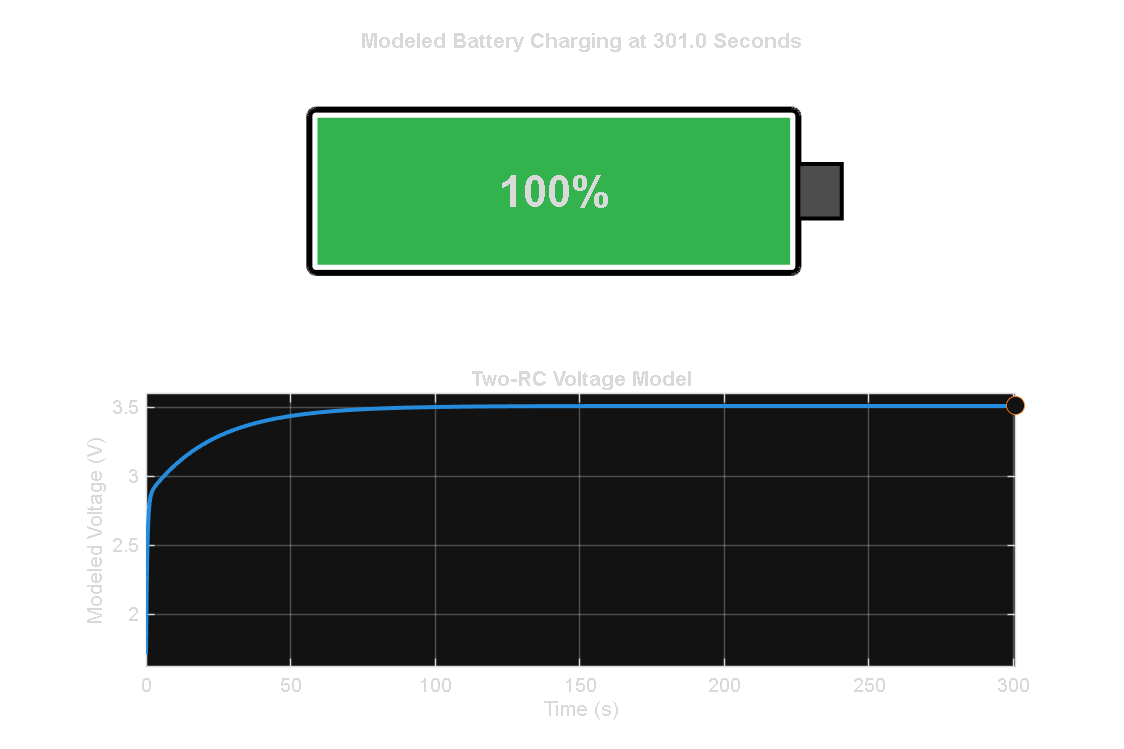

Battery animation saved to:
C:\Users\yngas\OneDrive\Desktop\BatteryProfile_Team6\results\animations\battery_model_charging.gif


%% Optional Battery-Fill GIF Animation

% Change this to true only when creating the GIF.
createBatteryAnimation = true;

if createBatteryAnimation

    % Confirm that the required variables exist.
    assert(exist('x','var') == 1, ...
        'Run the charging analysis before creating the animation.')

    assert(exist('twoRCVoltage','var') == 1, ...
        'Run the two-RC model section before creating the animation.')

    % Use the two-RC fitted voltage for the battery-fill animation.
    animationTime_s = x;
    animationVoltage_V = twoRCVoltage;

    % Convert the modeled voltage into a value from 0 to 1.
    % A value of 0 means empty and 1 means full.
    initialVoltage_V = animationVoltage_V(1);
    finalVoltage_V = animationVoltage_V(end);

    batteryFraction = ...
        (animationVoltage_V-initialVoltage_V) ./ ...
        (finalVoltage_V-initialVoltage_V);

    % Keep all fill values between 0 and 1.
    batteryFraction = max(0,min(1,batteryFraction));

    % Create the output folder when needed.
    if ~exist('animationFolder','var')
        animationFolder = fullfile(pwd,'results','animations');
    end

    if ~isfolder(animationFolder)
        mkdir(animationFolder)
    end

    gifFile = fullfile( ...
        animationFolder, ...
        'battery_model_charging.gif');

    % Remove an older GIF before creating the new one.
    if isfile(gifFile)
        delete(gifFile)
    end

    % Create the animation figure.
    animationFigure = figure( ...
        'Color','white', ...
        'Position',[100 100 900 600]);

    animationLayout = tiledlayout( ...
        animationFigure,2,1, ...
        'TileSpacing','compact');

    %% Battery Image

    batteryAxes = nexttile(animationLayout,1);

    hold(batteryAxes,'on')
    axis(batteryAxes,'equal')
    axis(batteryAxes,[0 12 0 5])
    axis(batteryAxes,'off')

    % Battery outline.
    rectangle( ...
        batteryAxes, ...
        'Position',[1 1 9 3], ...
        'Curvature',0.08, ...
        'LineWidth',3, ...
        'EdgeColor','black');

    % Battery terminal.
    rectangle( ...
        batteryAxes, ...
        'Position',[10 2 0.8 1], ...
        'FaceColor',[0.3 0.3 0.3], ...
        'EdgeColor','black', ...
        'LineWidth',2);

    % Battery fill. The width will change during the animation.
    batteryFill = rectangle( ...
        batteryAxes, ...
        'Position',[1.15 1.15 0 2.7], ...
        'FaceColor',[0.2 0.7 0.3], ...
        'EdgeColor','none');

    batteryPercentText = text( ...
        batteryAxes, ...
        5.5,2.5, ...
        '0%', ...
        'HorizontalAlignment','center', ...
        'VerticalAlignment','middle', ...
        'FontSize',22, ...
        'FontWeight','bold');

    batteryTitle = title( ...
        batteryAxes, ...
        'Modeled Battery Charging');

    %% Model Curve

    modelAxes = nexttile(animationLayout,2);

    plot( ...
        modelAxes, ...
        animationTime_s, ...
        animationVoltage_V, ...
        'LineWidth',2);

    hold(modelAxes,'on')

    movingPoint = plot( ...
        modelAxes, ...
        animationTime_s(1), ...
        animationVoltage_V(1), ...
        'o', ...
        'MarkerSize',9, ...
        'MarkerFaceColor','auto');

    xlabel(modelAxes,'Time (s)')
    ylabel(modelAxes,'Modeled Voltage (V)')
    title(modelAxes,'Two-RC Voltage Model')
    grid(modelAxes,'on')

    xlim(modelAxes,[min(animationTime_s) max(animationTime_s)])

    voltageMargin = 0.05 * ...
        (max(animationVoltage_V)-min(animationVoltage_V));

    ylim(modelAxes, ...
        [min(animationVoltage_V)-voltageMargin, ...
         max(animationVoltage_V)+voltageMargin]);

    %% Create GIF Frames

    % Limit the animation to approximately 100 frames.
    frameStep = max(1,floor(numel(animationTime_s)/100));

    frameIndex = unique( ...
        [1:frameStep:numel(animationTime_s), ...
         numel(animationTime_s)]);

    for frameNumber = 1:numel(frameIndex)

        k = frameIndex(frameNumber);

        currentFraction = batteryFraction(k);
        currentPercent = 100*currentFraction;

        % Update battery fill width.
        batteryWidth = 8.7*currentFraction;

        batteryFill.Position = ...
            [1.15 1.15 batteryWidth 2.7];

        % Update percentage text.
        batteryPercentText.String = ...
            sprintf('%.0f%%',currentPercent);

        % Update title.
        batteryTitle.String = sprintf( ...
            'Modeled Battery Charging at %.1f Seconds', ...
            animationTime_s(k));

        % Update the point on the modeled voltage curve.
        movingPoint.XData = animationTime_s(k);
        movingPoint.YData = animationVoltage_V(k);

        drawnow

        % Capture the current figure.
        frame = getframe(animationFigure);
        rgbImage = frame2im(frame);
        [indexedImage,colorMap] = rgb2ind(rgbImage,256);

        % Write the first frame, then append the remaining frames.
        if frameNumber == 1

            imwrite( ...
                indexedImage, ...
                colorMap, ...
                gifFile, ...
                'gif', ...
                'LoopCount',Inf, ...
                'DelayTime',0.08);

        else

            imwrite( ...
                indexedImage, ...
                colorMap, ...
                gifFile, ...
                'gif', ...
                'WriteMode','append', ...
                'DelayTime',0.08);

        end
    end

    fprintf('Battery animation saved to:\n%s\n',gifFile)

end